# PSF analysis

## data: each row is a code sequence 

data = [1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1;
    1, 1, 1, 1, 0, 0, 0, 1, 1, 1, 0, 0, 1, 1, 0, 1, 0, 1, 0, 0, 0, 1, 0, 0, 1, 0, 0, 0, 1, 1, 0, 1;
    0, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 1, 0, 0, 1, 1, 1, 0, 1, 0, 0, 0, 1, 1, 1;
    0, 0, 0, 1, 0, 1, 1, 0, 1, 0, 1, 0, 0, 0, 1, 1, 1, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 1, 1, 0, 1, 1;
    1, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 1, 0, 1, 1, 0, 1, 0, 1, 0, 0, 0, 0, 0, 0, 1, 1, 0, 0, 0, 0, 1;
    0, 0, 0, 1, 0, 0, 0, 1, 1, 1, 0, 0, 1, 1, 1, 1, 1, 1, 1, 1, 0, 1, 0, 0, 1, 0, 0, 0, 1, 1, 0, 0];

name = ["Non-coded", "Raskar et al.", "Agrawal et al.", "Jeon et al.", "Cui et al.","Ours"];

fft_point = 256;


## fft

data_num = size(data,1);

data_fft_norm = zeros(data_num,fft_point);
for k = 1:data_num
    fft_k = abs(fft(data(k,:), fft_point));
    data_fft_norm(k,:) = nthroot(fft_k,3);
    fft_k(fft_k==0) = eps; 
%     data_fft_norm(k,:) =log10(fft_k);
end

% data_fft(data_fft==-Inf) = -1e10;
% data_fft(data_fft==Inf) = 1e10;

## figure

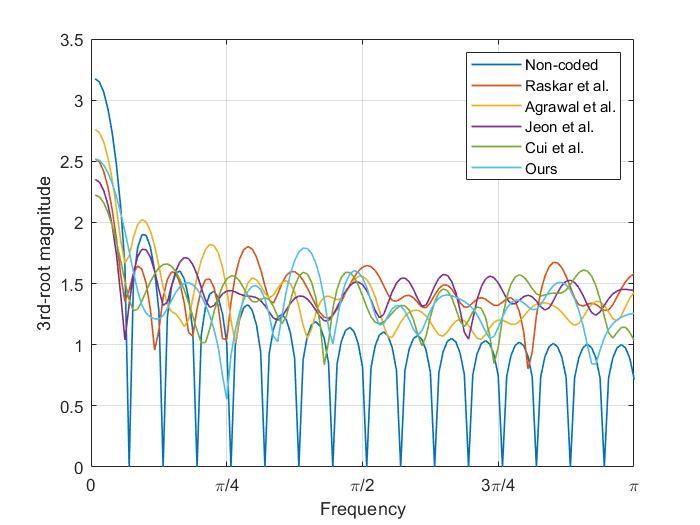

figureHandle=figure;
hold on

for  k = 1:data_num
    plot(data_fft_norm(k,:),'LineWidth',1)
end

% title('ce freq')
xlabel('Frequency')
ylabel('3rd-root magnitude')
xlim([0,fft_point/2])
xticks(linspace(0,fft_point/2,5))
xticklabels(["0" "\pi/4" "\pi/2" "3\pi/4" "\pi"])
legend(name)
box on
grid on


% plot(orig_fft_log,'LineWidth',2)
% plot(x12_fft_log,'LineWidth',2)
% plot(x16_fft_log,'LineWidth',2 )
% plot(x20_fft_log,'LineWidth',2 )
% legend('orig','x12','x16','x20')

% print
figW = 12;
figH = 8;
figureUnits = 'centimeters';
set(figureHandle,'PaperUnits',figureUnits);
set(figureHandle,'PaperPosition',[0 0 figW figH]);
fileout = 'abexp_fft';
% print(figureHandle,[fileout,'.png'],'-r600','-dpng');
% print(figureHandle,[fileout,'.pdf'],'-r600','-dpdf');
